clear all;
fstart = 1e9; fstop = 40e9; fpoints = 500;
f = linspace(fstart, fstop, fpoints);
l = 6e-6/16;

### Setup RLGCK Parameters

R_odd = linspace(0.8e6, 3.2e6, fpoints);
L_odd = (0.3.*exp(-f/f(1)) + 3.8)*1e-7;
G_odd = linspace(0, 60e-1, fpoints);
C_odd = linspace(1.5e-10, 1.4e-10, fpoints);
plotComponents(R_odd, L_odd, G_odd, C_odd, f);


R_even = linspace(0.8e6, 3.2e6, fpoints)/1.3;
L_even = (0.3.*exp(-f/f(1)) + 3.8)*1e-7/1.1;
G_even = linspace(0, 60e-1, fpoints)/1000;
C_even = linspace(1.5e-10, 1.4e-10, fpoints)/1000;
plotComponents(R_even, L_even, G_even, C_even, f);


Cst = 10*C_odd;

### Create Z-matrix 4-Port

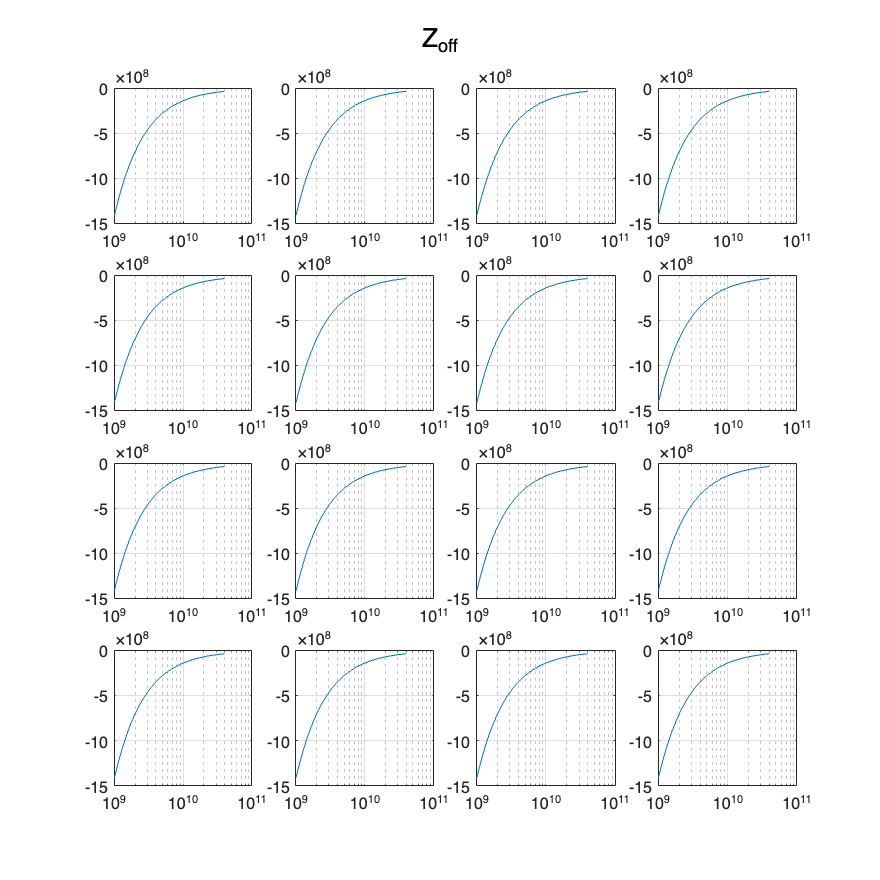

[gamma_odd_off, gamma_even_off, Z0_odd_off, Z0_even_off, theta_odd_off, theta_even_off, ...
          gamma_odd_on, gamma_even_on, Z0_odd_on, Z0_even_on, theta_odd_on, theta_even_on] = gamma_Z0(R_odd, L_odd, G_odd, C_odd, ...
                                                                         R_even, L_even, G_even, C_even, Cst, f, l);

[Z_on, Z_off] = Zparameters10(Z0_odd_off, Z0_even_off, Z0_odd_on, Z0_even_on, ...
                              theta_odd_off, theta_even_off, theta_odd_on, theta_even_on);

plot_Z_params(f, Z_off, 'Z_{off}');

plot_Z_params(f, Z_on, 'Z_{on}');

### Create Multiport ABCD

[ABCD_off, ABCD_on] = Z2ABCDmultiport(Z_off, Z_on, fpoints);

### Create combination matrix

num_of_sections = 3;
num_of_combinations = 2^num_of_sections;
% Generate all possible combinations of a 16-bit input
input_combinations = dec2bin(0:(num_of_combinations-1), num_of_sections) - '0';
% Convert the combinations to a MATLAB matrix (array)
input_matrix = input_combinations;

### Create Filters

% Initialize a cell array to store the identity matrices
identity_matrices = cell(1, fpoints);
% Create identity matrices and store them in the cell array
for i = 1:fpoints
    identity_matrices{i} = eye(4);
end
% Stack the identity matrices along the third dimension
I = cat(3, identity_matrices{:});
ABCD = I;
% Create a cell array to store S matrices
S_storage = cell(num_of_combinations, 1);

for index = 1:1:num_of_combinations
    for j = 1:1:num_of_sections
        if (input_matrix(index, j) == 1)
            ABCD = ABCD.*ABCD_on;
        else
            ABCD = ABCD.*ABCD_off;
        end
    end
    [Z, S] = ABCD2ZS(ABCD, fpoints);
    S_storage{index} = S;
end

plot_Ss(f, S_storage, 8);

function inv_A = invert_mat(A)
    [M, N, P] = size(A);
    inv_A = complex(zeros(M, N, P), zeros(M, N, P));
    
    for i = 1:P
        inv_A(:, :, i) = inv(A(:, :, i));
    end
end

function C = multiply_mat(A, B)
    [M, N, P] = size(A);
    C = complex(zeros(M, N, P), zeros(M, N, P));
    
    for i = 1:P
        C(:, :, i) = A(:, :, i) * B(:, :, i);
    end
end

function plotComponents(R_odd, L_odd, G_odd, C_odd, f)

    % Plot R_odd
    figure;
    subplot(2, 2, 1);
    plot(f, R_odd);
    title('Resistance (R\_odd)');
    xlabel('Frequency Points');
    ylabel('Resistance (\Omega)');

    % Plot L_odd
    subplot(2, 2, 2);
    plot(f, L_odd);
    title('Inductance (L\_odd)');
    xlabel('Frequency Points');
    ylabel('Inductance (H)');

    % Plot G_odd
    subplot(2, 2, 3);
    plot(f, G_odd);
    title('Conductance (G\_odd)');
    xlabel('Frequency Points');
    ylabel('Conductance (S)');

    % Plot C_odd
    subplot(2, 2, 4);
    plot(f, C_odd);
    title('Capacitance (C\_odd)');
    xlabel('Frequency Points');
    ylabel('Capacitance (F)');

    % Adjust layout
    sgtitle('Components vs Frequency Points');
end


function [gamma_odd_off, gamma_even_off, Z0_odd_off, Z0_even_off, theta_odd_off, theta_even_off, ...
          gamma_odd_on, gamma_even_on, Z0_odd_on, Z0_even_on, theta_odd_on, theta_even_on] = gamma_Z0(R_odd, L_odd, G_odd, C_odd, ...
                                                                         R_even, L_even, G_even, C_even, Cst, f, l)
    w = 2*pi*f;

    gamma_odd_off = sqrt((1i .* w .* L_odd + R_odd) .* (1i .* w .* C_odd + G_odd));
    gamma_even_off = sqrt((1i .* w .* L_even + R_even) .* (1i .* w .* C_even + G_even));
    Z0_odd_off = sqrt((R_odd + 1i .* w .* L_odd) ./ (G_odd + 1i .* w .* C_odd));
    Z0_even_off = sqrt((R_even + 1i .* w .* L_even) ./ (G_even + 1i .* w .* C_even));
    theta_odd_off = gamma_odd_off*l;
    theta_even_off = gamma_even_off*l;

    gamma_odd_on = sqrt((1i .* w .* L_odd + R_odd) .* (1i .* w .* (C_odd+Cst) + G_odd));
    gamma_even_on = sqrt((1i .* w .* L_even + R_even) .* (1i .* w .* C_even + G_even));
    Z0_odd_on = sqrt((R_odd + 1i .* w .* L_odd) ./ (G_odd + 1i .* w .* (C_odd+Cst)));
    Z0_even_on = sqrt((R_even + 1i .* w .* L_even) ./ (G_even + 1i .* w .* C_even));
    theta_odd_on = gamma_odd_on*l;
    theta_even_on = gamma_even_on*l;
end

function Z = create_Z_matrix(Z0_even, csc_theta_even, cot_theta_even, Z0_odd, csc_theta_odd, cot_theta_odd)
    Z11 = -(1j/2) * (Z0_even .* cot_theta_even + Z0_odd .* cot_theta_odd);
    Z12 = -(1j/2) * (Z0_even .* cot_theta_even - Z0_odd .* cot_theta_odd);
    Z13 = -(1j/2) * (Z0_even .* csc_theta_even - Z0_odd .* csc_theta_odd);
    Z14 = -(1j/2) * (Z0_even .* csc_theta_even + Z0_odd .* csc_theta_odd);

    Z = zeros(4, 4, length(Z11));

    Z(1, 1, :) = Z11;
    Z(2, 2, :) = Z11;
    Z(3, 3, :) = Z11;
    Z(4, 4, :) = Z11;

    Z(1, 2, :) = Z12;
    Z(2, 1, :) = Z12;
    Z(3, 4, :) = Z12;
    Z(4, 3, :) = Z12;

    Z(1, 3, :) = Z13;
    Z(3, 1, :) = Z13;
    Z(2, 4, :) = Z13;
    Z(4, 2, :) = Z13;

    Z(1, 4, :) = Z14;
    Z(4, 1, :) = Z14;
    Z(2, 3, :) = Z14;
    Z(3, 2, :) = Z14;
end

function [Z_on, Z_off] = Zparameters10(Z0_odd_off, Z0_even_off, Z0_odd_on, Z0_even_on, ...
                                                            theta_odd_off, theta_even_off, theta_odd_on, theta_even_on)
    % Calculate cotangents and cosecants for "off" and "on" states
    cot_theta_odd_off = 1 ./ tan(theta_odd_off);
    cot_theta_odd_on = 1 ./ tan(theta_odd_on);
    cot_theta_even_off = 1 ./ tan(theta_even_off);
    cot_theta_even_on = 1 ./ tan(theta_even_on);

    csc_theta_odd_off = 1 ./ sin(theta_odd_off);
    csc_theta_odd_on = 1 ./ sin(theta_odd_on);
    csc_theta_even_off = 1 ./ sin(theta_even_off);
    csc_theta_even_on = 1 ./ sin(theta_even_on);

    Z_off = create_Z_matrix(Z0_even_off, csc_theta_even_off, cot_theta_even_off, Z0_odd_off, csc_theta_odd_off, cot_theta_odd_off);
    Z_on = create_Z_matrix(Z0_even_on, csc_theta_even_on, cot_theta_even_on, Z0_odd_on, csc_theta_odd_on, cot_theta_odd_on);

end

function plot_Z_params(f, Z, title)
    gridSize = ceil(sqrt(16));
    fig_Z_params = figure;
    for i = 1:16
        subplot(gridSize, gridSize, i);
        semilogx(f, reshape(real(Z(floor((i-1)/4)+1, mod(i-1, 4)+1, :)), [1, length(f)]));
        grid on;
    end
    sgtitle(title, 'FontSize', 16);
    set(gcf, 'Position', [100, 100, 1500, 1500]);
end

function [ABCD_off, ABCD_on] = Z2ABCDmultiport(Z_off, Z_on, fpoints)
    Zee_off = Z_off(1:2, 1:2, :);
    Zei_off = Z_off(1:2, 3:4, :);
    Zie_off = Z_off(3:4, 1:2, :);
    Zii_off = Z_off(3:4, 3:4, :);

    Zee_on = Z_on(1:2, 1:2, :);
    Zei_on = Z_on(1:2, 3:4, :);
    Zie_on = Z_on(3:4, 1:2, :);
    Zii_on = Z_on(3:4, 3:4, :);

    ABCD_off = zeros(4, 4, fpoints); ABCD_on = ABCD_off;

    ABCD_off(1:2, 1:2, :) = multiply_mat(Zee_off, invert_mat(Zie_off));
    ABCD_off(1:2, 3:4, :) = multiply_mat(multiply_mat(Zee_off, invert_mat(Zie_off)), Zii_off) - Zei_off;
    ABCD_off(3:4, 1:2, :) = invert_mat(Zie_off);
    ABCD_off(3:4, 3:4, :) = multiply_mat(invert_mat(Zie_off), Zii_off);

    ABCD_on(1:2, 1:2, :) = multiply_mat(Zee_on, invert_mat(Zie_on));
    ABCD_on(1:2, 3:4, :) = multiply_mat(multiply_mat(Zee_on, invert_mat(Zie_on)), Zii_on) - Zei_on;
    ABCD_on(3:4, 1:2, :) = invert_mat(Zie_on);
    ABCD_on(3:4, 3:4, :) = multiply_mat(invert_mat(Zie_on), Zii_on);
end

function G0 = create_G0(Z1, Z2, Z3, Z4)
    G0 = zeros(4, 4, length(Z1), 'like', Z1);
    G0(1, 1, :) = 1./(abs(sqrt(real(Z1))));
    G0(2, 2, :) = 1./(abs(sqrt(real(Z2))));
    G0(3, 3, :) = 1./(abs(sqrt(real(Z3))));
    G0(4, 4, :) = 1./(abs(sqrt(real(Z4))));
end

function Z0 = create_Z0(Z1, Z2, Z3, Z4)
    Z0 = zeros(4, 4, length(Z1), 'like', Z1);
    Z0(1, 1, :) = Z1;
    Z0(2, 2, :) = Z2;
    Z0(3, 3, :) = Z3;
    Z0(4, 4, :) = Z4;
end

function [Z, S] = ABCD2ZS(ABCD, fpoints)
    Z = zeros(4, 4, fpoints);
    S = Z;
    Zin = 50*ones(1, fpoints);
    G0 = create_G0(Zin, Zin, Zin, Zin);
    Z0 = create_Z0(Zin, Zin, Zin, Zin);

    A = ABCD(1:2, 1:2, :);
    B = ABCD(1:2, 3:4, :);
    C = ABCD(3:4, 1:2, :);
    D = ABCD(3:4, 3:4, :);

    Z(1:2, 1:2, :) = multiply_mat(A, invert_mat(C));
    Z(1:2, 3:4, :) = multiply_mat(multiply_mat(A, invert_mat(C)), D) - B;
    Z(3:4, 1:2, :) = invert_mat(C);
    Z(3:4, 3:4, :) = multiply_mat(invert_mat(C), D);
    
    S = multiply_mat(G0, multiply_mat(Z-conj(Z0), multiply_mat(invert_mat(Z+Z0), invert_mat(G0))));
end

function plot_Ss(f, S_storage, n)
    N = length(S_storage);
    gridSize = ceil(sqrt(4));
    fig_S_params = figure;

    % Create a list of legend entries
    legend_entries = cell(1, N/n);
    for j = 1:N/n:N
        legend_entries{end+1} = ['index=' dec2bin(j-1, 8)];
    end

    % Add a legend to each subplot
    for i = 1:4
        subplot(gridSize, gridSize, i);
        for j = 1:N/n:N
            plot(f, reshape( (abs(S_storage{j}(floor((i-1)/2)+1, mod(i-1, 2)+1, :))) , [1, length(f)] ) );
            hold on;
        end
        grid on;
        hold off;
    end

    % Set a common title for all subplots
    sgtitle('S-parameters', 'FontSize', 16);
    legend(legend_entries, 'Location', 'Best');
    set(gcf, 'Position', [100, 100, 1000, 1000]);
end